# Calcolo Numerico con Laboratorio

# Compito a casa

# 08 novembre 2021

## Esercizio 1

Si consideri la funzione $f(x)=\cosh(x)+\cos(x)-\gamma$ per $\gamma=1,2,3$.

- Rappresentare al variare i $\gamma$ la funzione e individuare, se possibile, un intervallo contenente uno zero di $f$ .

- Applicare il metodo di Newton per determinare gli eventuali zeri nell'intervallo individuato precedentemente, usando come dati iniziali $x_0=1$ e $x_0=-0.5$e `toll=1e-10`. Riportare lo zero sul grafico della funzione.

- Per ogni caso, calcolare la differenza fra due iterate successive e plottarla in un grafico in scala semilogaritmica riportando in un unico grafico i risultati corrispondenti ai due dati iniziali in relazione a ciascun  valore di $\gamma$.

- Nel file `bisezione.m` è implementato il metodo di bisezione. Scegliendo opportunamente un intervallo, calcolare gli eventuali zeri di $f$ per ciascun valore di $\gamma$. Confrontare con i risultati ottenuti con il metodo di Newton e commentare le eventuali differenze.

clear all
close all
syms x;
for y=1:3
    subplot(2,3,y)
    hold on
    title("funzione y="+y)
    f=cosh(x)+cos(x)-y;
    fplot(f)
    subplot(2,3,y+3)
    semilogy(y)
    for x0 = -0.5:1.5: 1
        [zero,fz,iter,output]=newton(f,x0,1e-10,100);
        if iter<100 && fz<inf
            subplot(2,3,y)
            plot(zero,fz,'*r')
            diff=[];
            for i=1:length(output)-1
                diff=[diff abs(output(i+1)-output(i))];
                subplot(2,3,y+3)
                hold on
                semilogy(diff)
                title("andamento errore per iterazione y="+y)
            end
        end
        if x0==-0.5
            [zero,fz,iter,flag]=bisezione(matlabFunction(f),-5,0,1e-10,100);
        else
            [zero,fz,iter,flag]=bisezione(matlabFunction(f),0,5,1e-10,100);
        end
        if iter<100 && flag
            subplot(2,3,y)
            plot(zero,fz,'og')
        end
    end
    subplot(2,3,y)
    legend("funzione","Newton","bisezione")
end

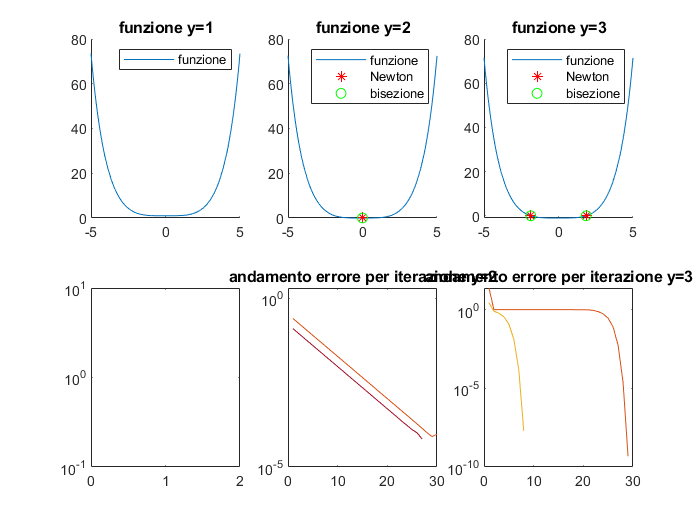

savefig("Esercizio1")

Col metodo della bisezione nel caso di y=2 essendo che la funzione è sempre positiva tranne che per il punto di zero se non si conosce con certezza il punto di zero questo metodo non è in grado di trovarlo, mentre quello di newton non ha nessun problema.

## Esercizio 2

Usare la function `newton `per calcolare gli zeri delle seguenti funzioni, con `x0` assegnato:

- $f (x) = (x^3 + 3)(\cos(x-1)-x^2 + 2x)- 8$   dato iniziale `x0=[-2,-1,0]`

- $f (x) = x^3 - 7x^2 + 11x - 5$    dato iniziale `x0=[2,7]`

- $f (x) = x^4 - 12x^3 + 47x^2 - 60x + 24$    dato iniziale  `x0=[0,2]`

Porre `toll=1e-10` e `nmax=100 `nella function `newton.`

Fare un grafico di ciascuna funzione e riportare sul grafico lo zero ottenuto.

Riportare la successione generata con il metodo di Newton.

Riportare in scala semilogaritmica la differenza fra due iterate successive ottenute e commentare il risultato.

Commentare sul file LiveScript del compito i riultati ottenuti:

- osservando il grafico della soluzione, qual è la molteplicità degli zeri?

- qual è l'ordine di convergenza del metodo di Newton in ciascun caso?  

Consegnare anche il file `newton.m`

clear all
close all
syms x;
toll=1e-10;nmax=100;
f=(x^3+3)*(cos(x-1)-x^2+2*x)-8;
df=matlabFunction(diff(f));
index=0;
for x0=[-2,-1,0]
    [zero,fz,iter,output]=newton(f,x0,toll,nmax);
    if iter<nmax&&fz<inf
        if round(df(zero))==0
            disp("per x0="+x0+" si ha uno zero doppio")
            disp("ordine di convergenza 1")
        else
            disp("per x0="+x0+" si ha uno zero singolo")
            disp("ordine di convergenza 2")
        end
        subplot(3,3,1+index*3)
        fplot(f)
        title("x0="+x0)
        hold on
        plot(zero,fz,'or')
        subplot(3,3,2+index*3)
        plot(output)
        title("andamento iterazioni x0="+x0)
        diff=[];
        for i=1:length(output)-1
            diff=[diff abs(output(i+1)-output(i))];
        end
        subplot(3,3,3+index*3)
        semilogy(diff)
        title("errore iterazioni x0="+x0)
    end
    index=index+1;
end

per x0=-2 si ha uno zero singolo


ordine di convergenza 2


per x0=-1 si ha uno zero singolo


ordine di convergenza 2


per x0=0 si ha uno zero singolo


ordine di convergenza 2


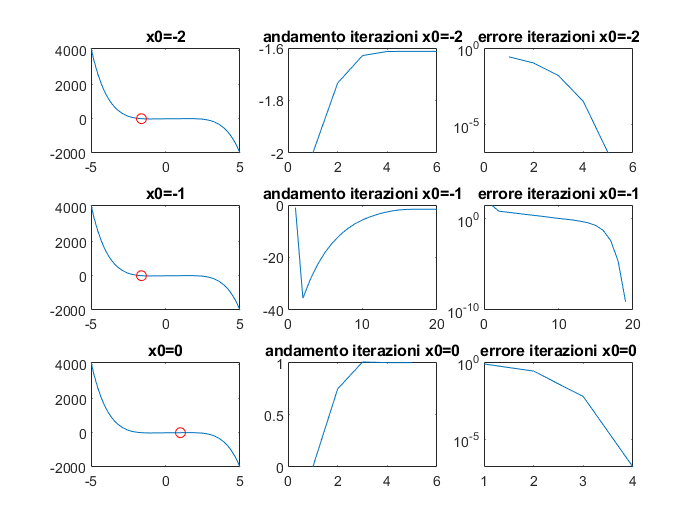

savefig("Es2_fun1")

clear all
close all
syms x;
toll=1e-10;nmax=100;
f=x^3-7*x^2+11*x-5;
df=matlabFunction(diff(f));
index=0;
for x0=[2,7]
    [zero,fz,iter,output]=newton(f,x0,toll,nmax);
    if iter<nmax&&fz<inf
        if round(df(zero))==0
            disp("per x0="+x0+" si ha uno zero doppio")
            disp("ordine di convergenza 1")
        else
            disp("per x0="+x0+" si ha uno zero singolo")
            disp("ordine di convergenza 2")
        end
        subplot(2,3,1+index*3)
        fplot(f,[0 10])
        title("x0="+x0)
        hold on
        plot(zero,fz,'or')
        subplot(2,3,2+index*3)
        plot(output)
        title("andamento iterazioni x0="+x0)
        diff=[];
        for i=1:length(output)-1
            diff=[diff abs(output(i+1)-output(i))];
        end
        subplot(2,3,3+index*3)
        semilogy(diff)
        title("errore iterazioni x0="+x0)
    end
    index=index+1;
end

per x0=2 si ha uno zero doppio


ordine di convergenza 1


per x0=7 si ha uno zero singolo


ordine di convergenza 2


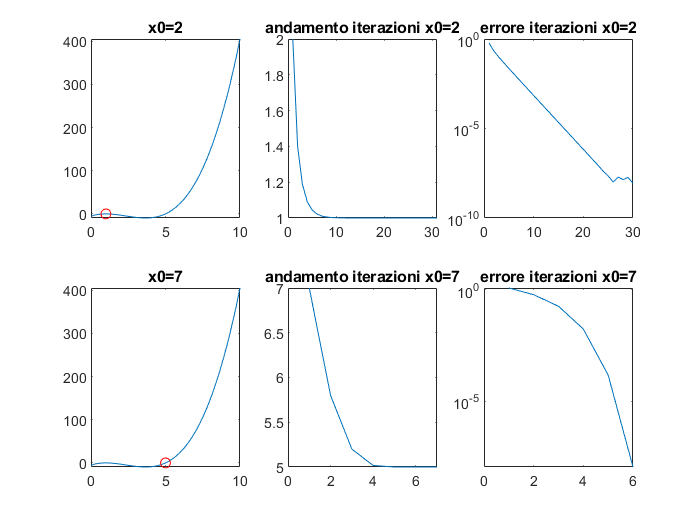

savefig("Es2_fun2")

clear all
close all
syms x;
toll=1e-10;nmax=100;
f=x^4-12*x^3+47*x^2-60*x+24;
df=matlabFunction(diff(f));
index =0;
for x0=[0,2]
    [zero,fz,iter,output]=newton(f,x0,toll,nmax);
    if iter<nmax&&fz<inf
        if round(df(zero))==0
            disp("per x0="+x0+" si ha uno zero doppio")
            disp("ordine di convergenza 1")
        else
            disp("per x0="+x0+" si ha uno zero singolo")
            disp("ordine di convergenza 2")
        end
        subplot(2,3,1+index*3)
        fplot(f,[0 10])
        title("x0="+x0)
        hold on
        plot(zero,fz,'or')
        subplot(2,3,2+index*3)
        plot(output)
        title("andamento iterazioni x0="+x0)
        diff=[];
        for i=1:length(output)-1
            diff=[diff abs(output(i+1)-output(i))];
        end
        subplot(2,3,3+index*3)
        semilogy(diff)
        title("errore iterazioni x0="+x0)
    end
    index=index+1;
end

per x0=0 si ha uno zero singolo


ordine di convergenza 2


per x0=2 si ha uno zero singolo


ordine di convergenza 2


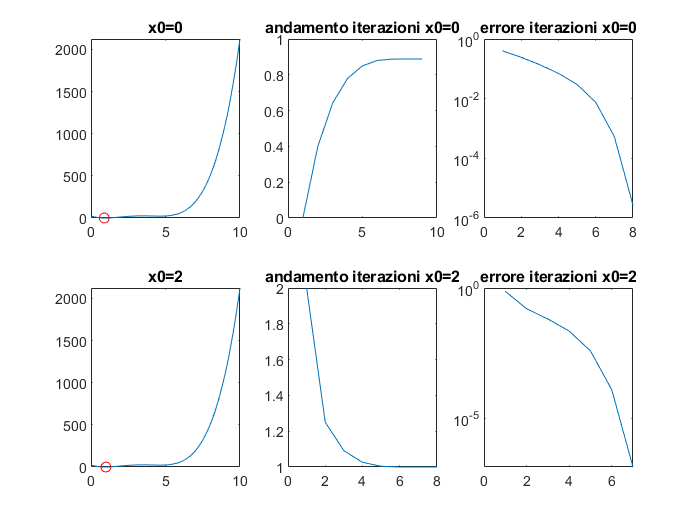

savefig("Es2_fun3")

## Esercizio 3

Si consideri la funzione

$f(x)=\sin(x)(x-\pi)+\cos(x+\pi)-1$ per $x\in[-2\pi, 2\pi]$.

- Rappresentare la funzione data insieme all'asse delle $x$;

- risolvere l'equazione $f(x)=0$ con il metodo di Newton usando i seguenti valori per il dato iniziale $x_0=-4$, $x_0=-1$ e $x_0=2$  (`toll=1.e-8`, `nmax=20`);

- marcare i valori ottenuti sul grafico della funzione;

- usando gli stessi dati iniziali, calcolare gli zeri con la function `fzero` di Matlab, marcare i risultati ottenuti nel grafico della funzione e dire se sono gli stessi di quelli ottenuti con il metodo di Newton;

- confrontare il numero di valutazioni utilizzate da` fzero` e da `newton` nel caso in cui calcolino lo stesso zero.

clear all
close all
syms x;
f=sin(x)*(x-pi)+cos(x+pi)-1;
a=-2*pi;b=2*pi;
subplot(1,3,1)
fplot(f,[a b])
hold on
asseX([a,b])
title("zeri Newton")
subplot(1,3,2)
fplot(f,[a b])
hold on
asseX([a,b])
title("zeri fzero")
toll=1e-14;Nmax=20;
diff=[];
for x0=[-4, -1, 2]
    subplot(1,3,1)
    [zeroN,fzN,iterN]=newton(f,x0,toll,Nmax);
    plot(zeroN,fzN,'or')
    subplot(1,3,2)
    [zeroF,fzF,flag,output]=fzero(matlabFunction(f),x0);
    plot(zeroF,fzF,'og')
    if round(zeroF,1)==round(zeroN,1)
        iterF=output.iterations+output.intervaliterations;
        diff=[diff iterF-iterN];
        disp("valore di partenza = "+x0)
        disp("iterazioni fzero - iterazioni Newton = "+(iterF-iterN))
        disp("valore funzione in zero Newton = "+fzN)
        disp("valore funzione in zero fzero = "+fzF)
    end
    
end

valore di partenza = -4


iterazioni fzero - iterazioni Newton = 7


valore funzione in zero Newton = 6.6613e-16


valore funzione in zero fzero = 3.5527e-15


valore di partenza = -1


iterazioni fzero - iterazioni Newton = 12


valore funzione in zero Newton = -2.2204e-16


valore funzione in zero fzero = 2.2204e-16


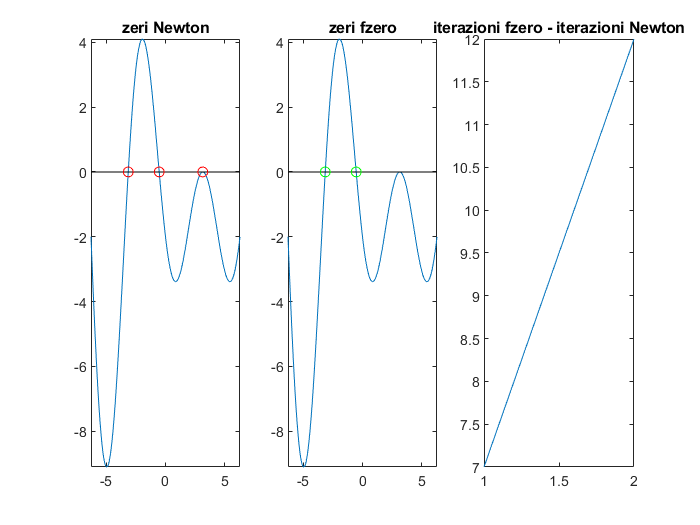

subplot(1,3,3)
plot(diff)
title("iterazioni fzero - iterazioni Newton")
savefig("Esercizio3")

Come si vede il metodo di Newton arriva a risultato in un numero inferiore di iterazioni rispetto alla funzione fzero di Matlab, questo può essere giustificato dal fatto che le condizioni di convergenza della funzione fzero sono meno stringenti.